***Martelet Curtis - Giordano Dylan                   L3 EEA-Groupe TP1***

## **Compte-rendu TDP3**

## **Hacheur serie: Etude des valeurs moyennes**

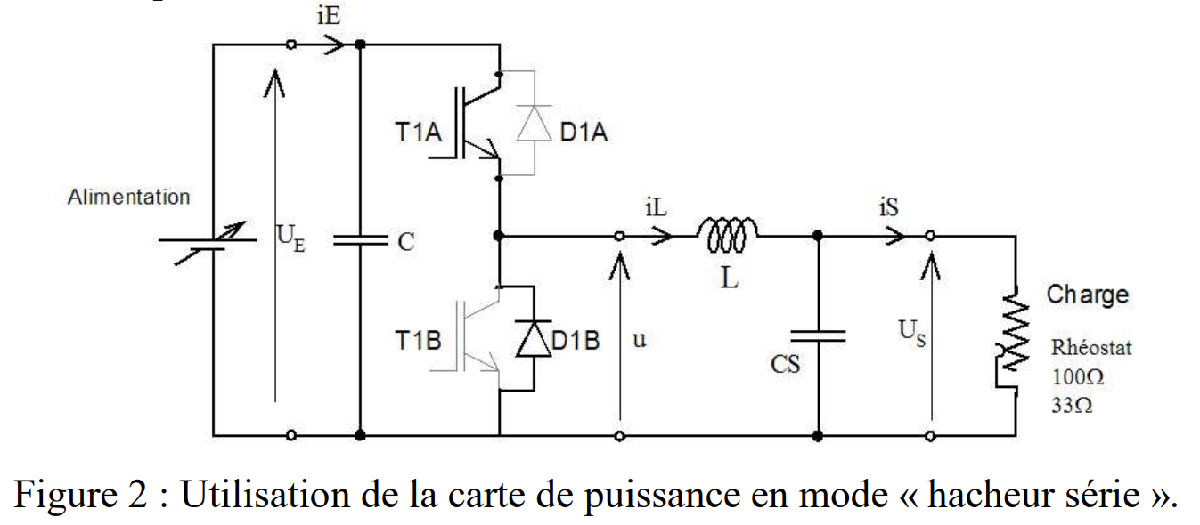

# **Mesures de valeurs moyennes:**

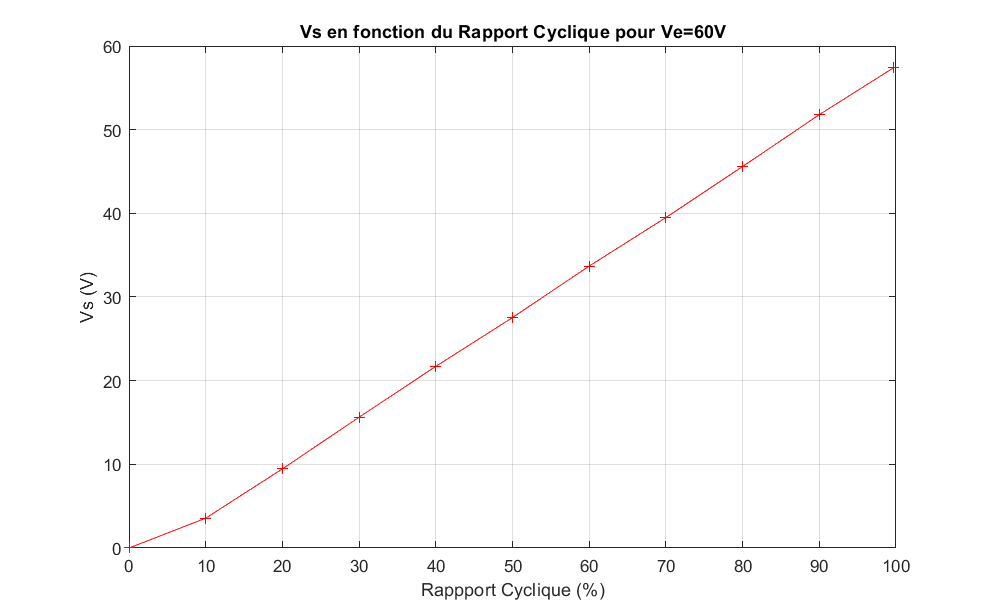

clc

% CONVERSION Partie 1
% Ve = 60V
rapport_cycle=[99.68 90 80 70 60 50 40 30 20 10 0];
Vs=[57.4 51.8 45.60 39.50 33.70 27.55 21.71 15.64 9.46 3.57 0];

plot(rapport_cycle,Vs,'r+-'); % Vs=f(alpha)
title('Vs en fonction du Rapport Cyclique pour Ve=60V')
xlabel('Rappport Cyclique (%)'); ylabel('Vs (V)')
grid on

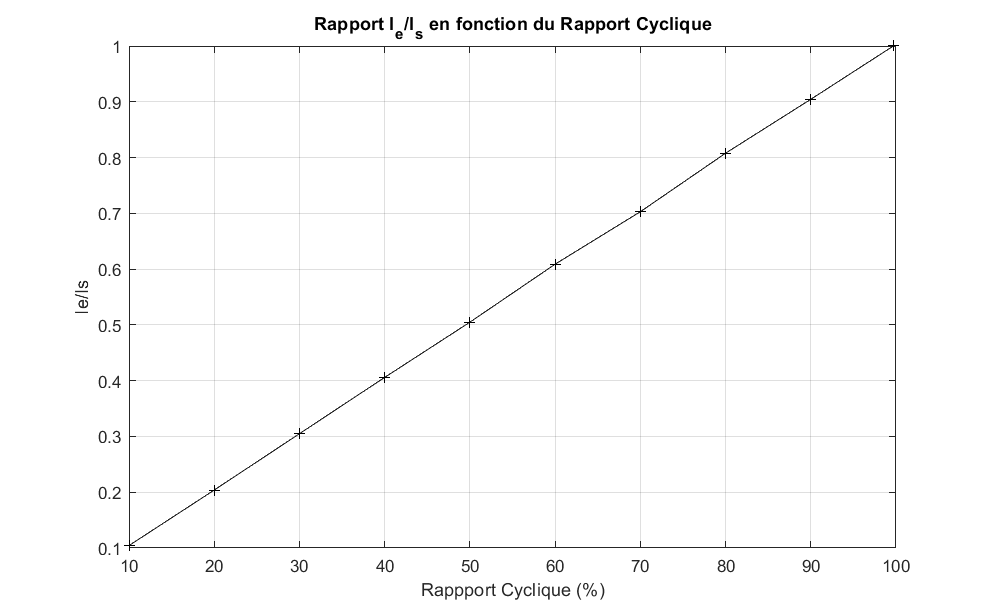




Ie=[2 1.80 1.64 1.42 1.23 1.02 0.82 0.61 0.41 0.21 0];
Is=[2.00 1.99 2.03 2.02 2.02 2.02 2.02 2 2.01 2.01 0];

plot(rapport_cycle,Ie./Is,'k+-'); %%Ie/Is=f(alpha)
title('Rapport I_e/I_s en fonction du Rapport Cyclique')
xlabel('Rappport Cyclique (%)'); ylabel('Ie/Is')
grid on

Pour la premiere courbe, nous avons la relation Vs= α*Ve, la courbe obtenue est donc une droite.

Pour la seconde courbe, nous pouvons constater que le rapport des courants Ie/Is est proportionnel au rapport cyclique.

En effet, dans ce mode de fonctionnement, Pe=Ps donc nous avons la relation : Ie=( **α***Is).

# **Mesures temporelles:**

% Image d'ALI.

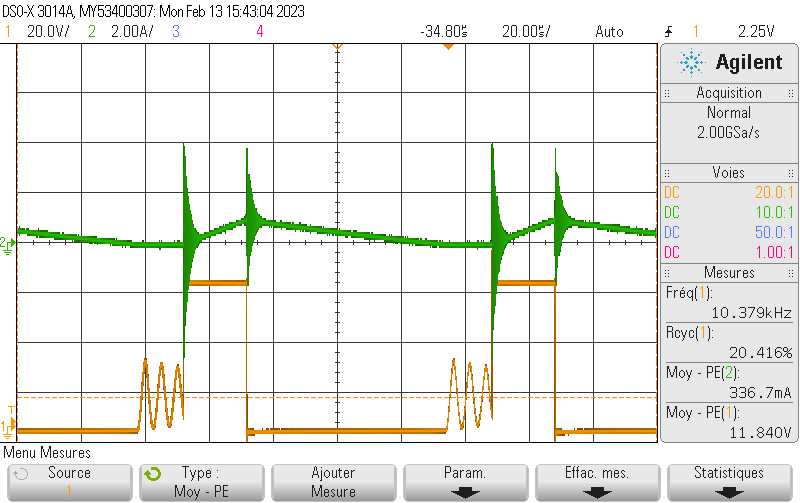

Cette capture d'ecran correspond a un mode de fonctionnement en conduction discontinue pour le hacheur serie.

C'est un mode de fonctionnement a eviter car cela modifie la tension de sortie Vs.

Cela est provoque par un courant dans la charge trop faible qui ne permet pas a la bobine d'etre completement charge avant la fin d'une periode de commutation.

Afin de regler ce probleme et etre en mode de commutation continue, il suffit de diminuer la valeur de la charge pour avoir un courant de sortie plus important.

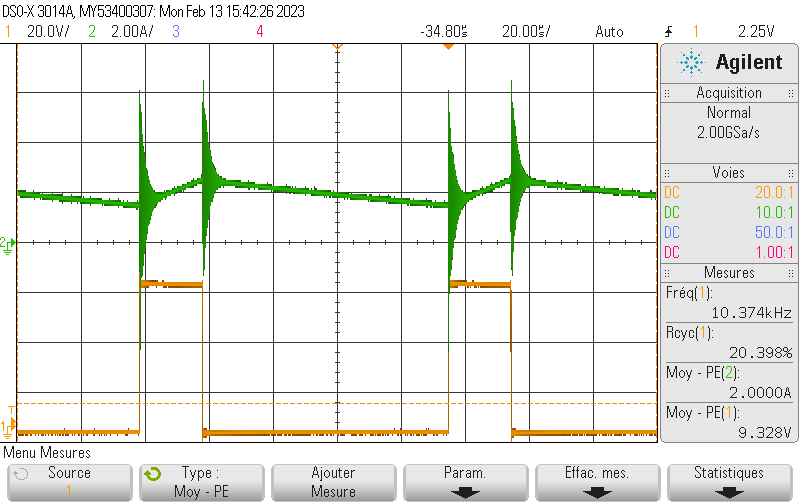

La seconde capture est le mode de commutation continue.

**Entre 0 et αT, le transistor est passant et la diode est bloquee. Nous avons U=Ue.**

**Entre αT et T, le transistor est bloque et la diode passante, nous avons U=0V.**

La courbe verte est l'evolution du courant iL, nous pouvons observer qu'il s'agit de la derive de la courbe orange.

# Ondulation du courant iL:

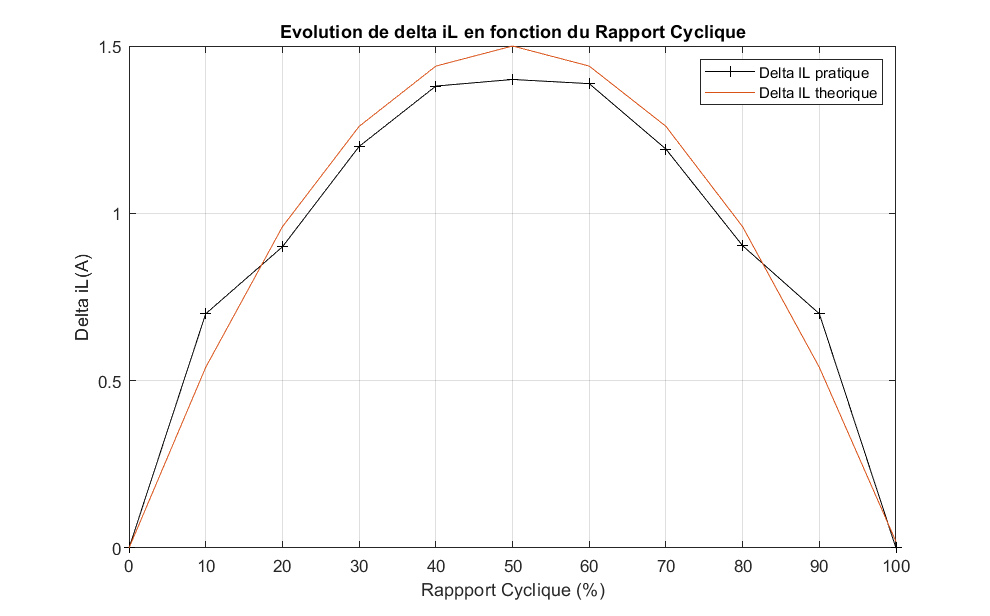

% Ondulation de courant Il
rapport_cycle=[100 90 80 70 60 50 40 30 20 10 0];
delta_Il=[0 700 903.25 1192 1387.5 1400 1380.3 1200 900 700 0]*1e-3;
delta_IL_th=[0.0191 0.54 0.96 1.26 1.44 1.50 1.44 1.26 0.96 0.54 0];

plot(rapport_cycle,delta_Il,'k+-',rapport_cycle,delta_IL_th);

title('Evolution de delta iL en fonction du Rapport Cyclique');
xlabel('Rappport Cyclique (%)'); 
ylabel('Delta iL(A)');
legend(["Delta IL pratique","Delta IL theorique"])
grid on

# Etude qualitative du fonctionnement:

On modifie uniquement un seul des paramètres a la fois :

- **Rapport cyclique :** faire varier le rapport cyclique fait également varier la tension de sortie entre 0 et Ve (Vs=α*Ve).

- **Ve :** faire varier la tension d'entrée fera également et uniquement varier la tension de sortie. Si la tension d'entrée est cependant inferieure a la tension de sortie d'usine du hacheur, alors ce dernier se mettra en securité (dans le cas de notre hacheur).

- **R :** modifier la charge changera la valeur du courant Is : plus la resistance sera grande plus Is sera petit ainsi que la valeur de le car on a le=(α*Is)

- **Fe :** modifier la fréquence de découpage aura un impact sur la qualite du signal en sortie du hacheur. Plus cette fréquence sera petite, plus le regime transitoire (conduction discontinue) sera apparent sur le signal (on verra en sortie un signal en dent de scie).

- **L : **enfin, modifier L aura le méme effet que de faire varier Fe. En la diminuant, le signal de sortie ne sera pas lisser correctement, et donc rendra les creneaux visibles (conduction discontinue donc signal en dent de scie).

# Tension de sortie reglable a partir d’une source de tension fixe

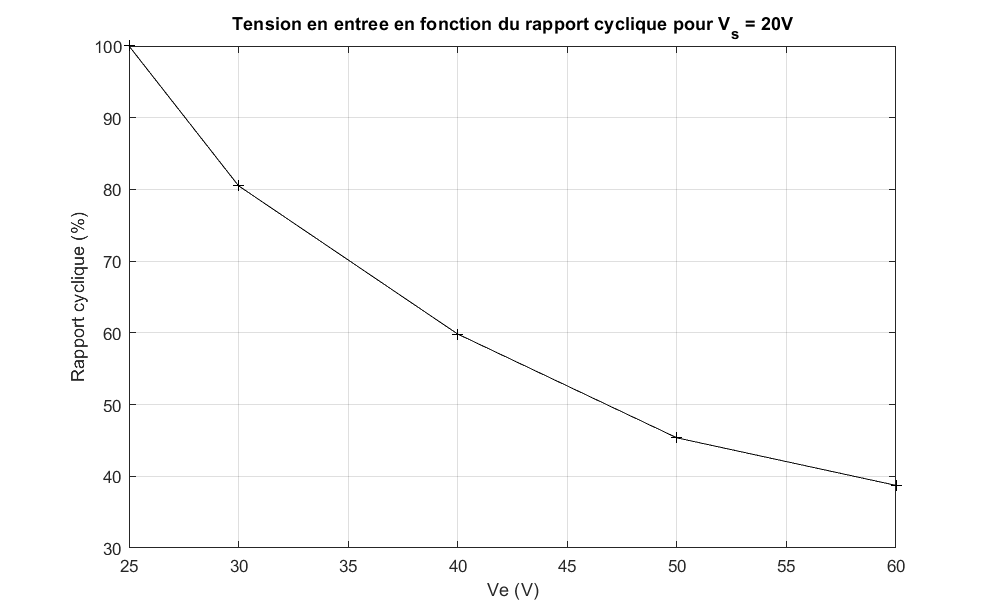

% CONVERSION Partie 2
Ps=60;
alpha3=[100 80.5 59.83 45.36 38.73];
Ve2=[25 30 40 50 60];
Ie2=[3.09 2.46 1.82 1.45 1.28];

plot(Ve2,alpha3,'k+-');
title('Tension en entree en fonction du rapport cyclique pour V_s = 20V')
xlabel('Ve (V)'); ylabel('Rapport cyclique (%)');
grid on

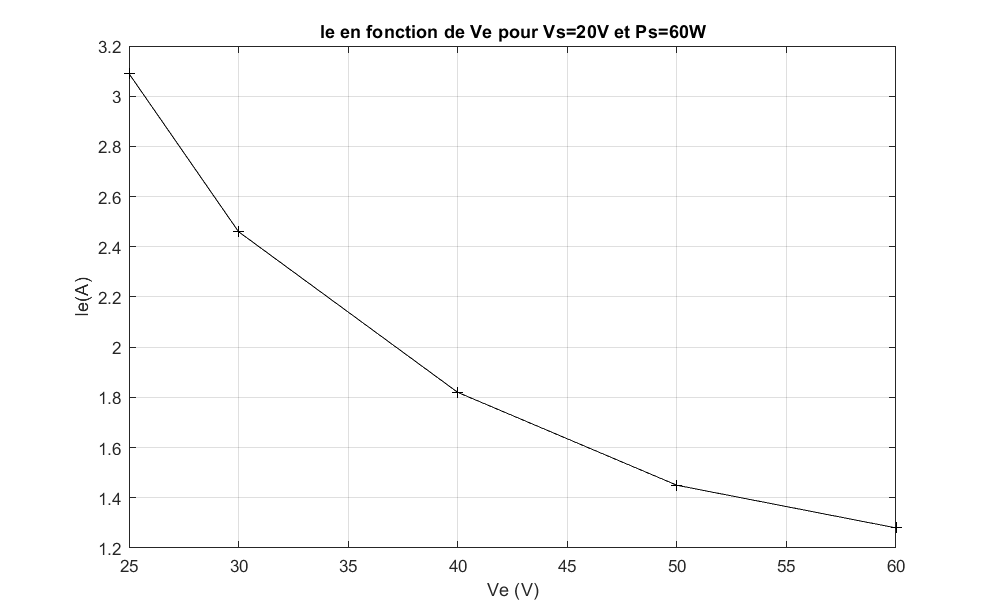

plot(Ve2,Ie2,'k+-');
title('Ie en fonction de Ve pour Vs=20V et Ps=60W')
xlabel('Ve (V)'); ylabel('Ie(A)')
grid on

On peut observer que la courbe du rapport cyclique en fonction de la tension d'entrée et du courant en entrée en fonction de la tension en entrée ont la méêe allure.

On peut donc suggérer que le rapport cyclique influence la valeur du courant d'entrée : pour un a=100%, le=3.1A ; pour a=60%, le=1.8 => le = a*le max.

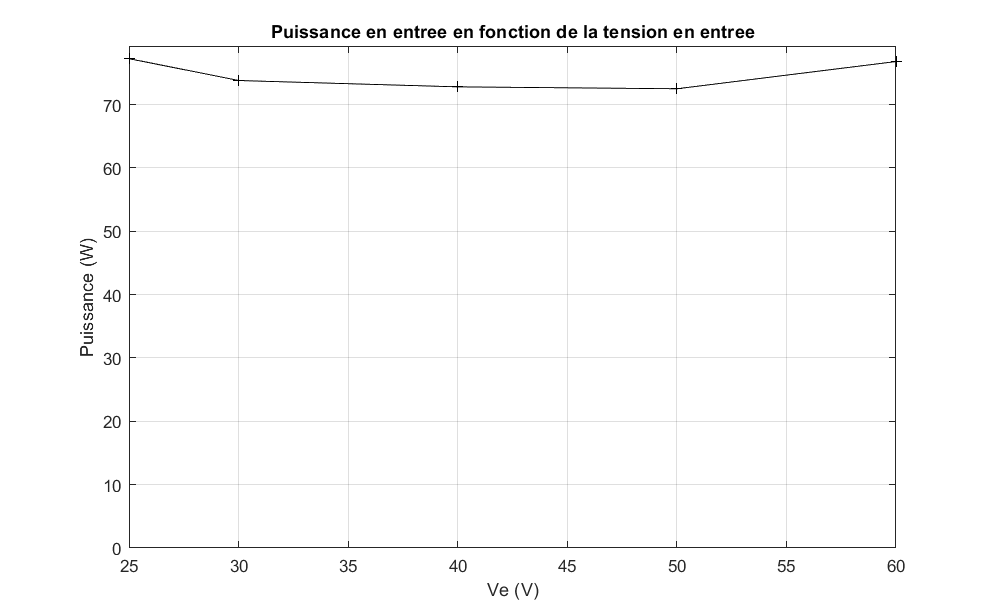

Pe=Ve2.*Ie2;

plot(Ve2,Pe,'k+-');
title('Puissance en entree en fonction de la tension en entree')
xlabel('Ve (V)'); ylabel('Puissance (W)')
ylim([0 max(Pe)+2])
grid on

On peut observer que la puissance en entrée reste constant en fonction de la tension en entrée (P=U*1).

Dans la premiére courbe, on a pu observer que le courant d'entrée variait en fonction du rapport cyclique (le = a*le max). On peut donc conclure que le rapport cyclique permet d'avoir Pe constant qu'importe la valeur de Ve (quand Ve monte, le diminue).

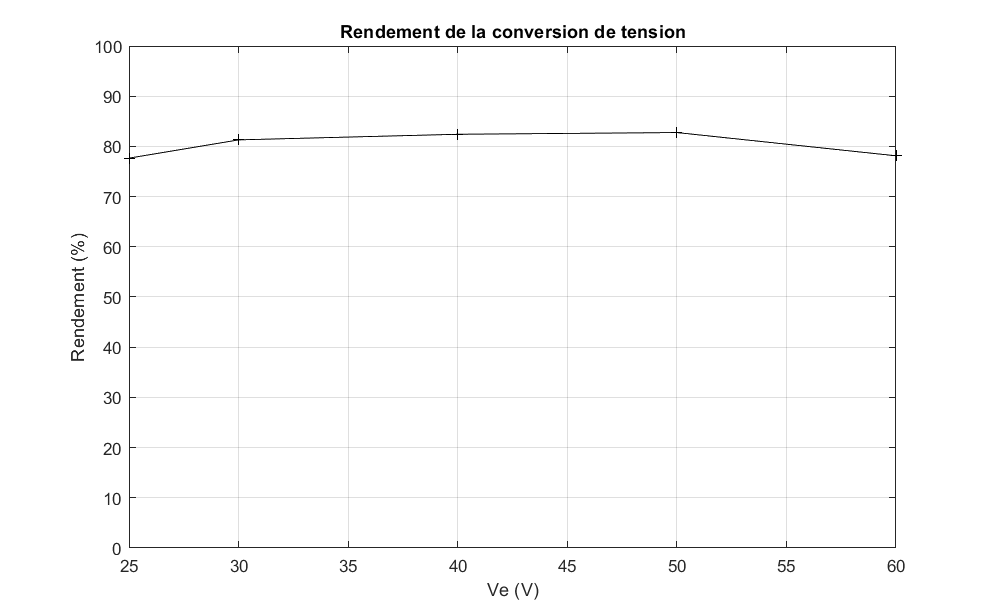

rendement=(Ps./Pe)*100;
plot(Ve2,rendement,'k+-');
title('Rendement de la conversion de tension')
xlabel('Ve (V)'); ylabel('Rendement (%)')
ylim([0 100])
grid on

La courbe du rendement est, comme la courbe de la puissance en entrée, constante. D'ailleurs, cette courbe est également identique & celle du rendement dans le cadre du TP1 (dans le cas de I'alimentation a découpage).

Dans le cadre de cet exercice, on a fixé Ps = 60W. Or, on a vu avec la courbe précédente que Pe restait constant qu'importe Ve. On a donc un rendement constant puisque ces deux grandeurs sont des (quasi) constantes.